# 2 Motor Step Response Experiment

#### Demo 1 for SEED Lab

Alex Curtis

This script will find transfer functions for both motors using step response data, and find eventually create a controller to make sure the robot moves in a straight line.

This script runs the step response experiment I created in stepResponse.ino, interperets the data, makes some beautiful plots, determines an accurate transfer function for the motor, and tunes a PI controller to desired specifications. 

*Upload the stepResponse code to the Arduino before running.*

#### Clear previous workspace data

clear

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard)

ans = "Start!"

#### Tell the Arduino to start the forward velocity experiment (#1)

disp('Starting forward velocity experiment in Arduino')

Starting forward velocity experiment in Arduino


writeline(ard,"1"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index
% stringArray = zeros(1001,5); % preallocate

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished1',9)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end
% writeline(ard,"E");
clear newData ard; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Create a table to store the data
exp1 = array2table(dataArray,"VariableNames",{'time', 'posL', 'posR', 'fVel', 'rVel'});
%dataTable = array2table(dataArray,"VariableNames",{'time', 'fVel', 'rVel'})
%dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'phidot', 'rhodot', 'nright', 'nleft'})
% Save data to a .mat file
save steerData.mat exp1
clear dataArray stringArray newData

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard)

ans = "Start!"

#### Tell the Arduino to start the rotational velocity experiment (#2)

disp('Starting rotational velocity experiment in Arduino')

Starting rotational velocity experiment in Arduino


writeline(ard,"2") % sends the start command to the Arduino

Read data from Arduino

k2 = 0; % array index
% stringArray = zeros(1001,5); % preallocate

% Read the first line of output from the Arduino
newData = readline(ard)

newData = "1000	0	0	0.0000	0.0000"


% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished2',9)) 
    k2 = k2 + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k2,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear ard; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

exp2 = array2table(dataArray,"VariableNames",{'time', 'posL', 'posR', 'fVel', 'rVel'});
%dataTable2 = array2table(dataArray,"VariableNames",{'time', 'fVel', 'rVel'})

Manually find rho_dot and phi_dot to hopefully fix the noise issue

WHEEL_RADIUS = 2.95;              %Radius of wheel in inches
WHEELBASE = 13.974;
rho_dot1(k,1) = 0;
phi_dot1(k,1) = 0;
rho_dot2(k2,1) = 0;
phi_dot2(k2,1) = 0;
CONVERSION = (WHEEL_RADIUS*2.0*pi)/3200;
% rho_dot2(i) = CONVERSION*(exp2.posR(i) - exp2.posR(i-1) + exp2.posL(i) - exp2.posL(i-1))/(2.0*(exp2.time(i)-exp2.time(i-1)));
% phi_dot2(i) = 0;
% rho_dot1(i) = 0;
% phi_dot1(i) = 0;
for i = 2:k
    rho_dot1(i,1) = CONVERSION*(exp1.posR(i) - exp1.posR(i-1) + exp1.posL(i) - exp1.posL(i-1))/(2.0*(exp1.time(i)-exp1.time(i-1)));
    phi_dot1(i,1) = CONVERSION*(exp1.posL(i) - exp1.posL(i-1) - exp1.posR(i) + exp1.posR(i-1))/(WHEELBASE*(exp1.time(i)-exp1.time(i-1)));
end

for i = 2:k2
    rho_dot2(i,1) = CONVERSION*(exp2.posR(i) - exp2.posR(i-1) + exp2.posL(i) - exp2.posL(i-1))/(2.0*(exp2.time(i)-exp2.time(i-1)));
    phi_dot2(i,1) = CONVERSION*(exp2.posL(i) - exp2.posL(i-1) - exp2.posR(i) + exp2.posR(i-1))/(WHEELBASE*(exp2.time(i)-exp2.time(i-1)));
end

exp1.newRho = rho_dot1;
exp1.newPhi = phi_dot1

exp1 = 101×7 table
    time    posL    posR     fVel      rVel      newRho     newPhi  
    ____    ____    ____    ______    _______    ______    _________

       0      0       0          0          0         0            0
    0.01      6       6     3.8615          0    3.4754            0
    0.02     22      24     10.941    -0.0921    9.8469    -0.082901
    0.03     44      45     13.837     0.0461    12.453     0.041451
    0.04     76      75     19.951     0.0921    17.956     0.082901
    0.05    114     112     24.135     0.0461    21.721     0.041451
    0.06    157     155     27.674          0    24.907            0
    0.07    200     196     27.031     0.0921    24.328     0.082901
    0.08    251     247     32.823          0    29.

exp2.newRho = rho_dot2;
exp2.newPhi = phi_dot2

exp2 = 101×7 table
    time    posL    posR     fVel      rVel     newRho     newPhi 
    ____    ____    ____    ______    ______    _______    _______

       0      0        0         0         0          0          0
    0.01      4       -4         0    0.3685          0    0.33161
    0.02     21      -19    0.6436    1.4738    0.57923     1.3264
    0.03     43      -40    0.3218    1.9804    0.28962     1.7824
    0.04     72      -67    0.6436    2.5792    0.57923     2.3212
    0.05    109     -104         0    3.4082          0     3.0673
    0.06    152     -146    0.3218    3.9148    0.28962     3.5233
    0.07    199     -193         0    4.3293          0     3.8964
    0.08    245     -238    0.3218    4.1911    0.28962      3.772
    0

#### Plot the data (raw motor response)

%t = tiledlayout(1,2,'TileSpacing','Compact','Padding','tight');
t = tiledlayout(2,2,'TileSpacing','Compact','Padding','tight');

nexttile;
plot(exp1.time,exp1.fVel,exp1.time,exp1.newRho);
title('Exp 1 Forward Vel');
ylabel('Velocity (in/s)');
grid on;

nexttile;
plot(exp1.time, exp1.rVel,exp1.time,exp1.newPhi);
title('Exp 1 Rotational Vel');
grid on;

xlabel('Time (s)');
grid on;

nexttile;
plot(exp2.time,exp2.fVel,exp2.time,exp2.newRho);
title('Exp 2 Forward Vel')
ylabel('Velocity (in/s)');
grid on;

nexttile;
plot(exp2.time, exp2.rVel,exp2.time,exp2.newPhi);
title('Exp 2 Rotational Vel');
grid on

xlabel('Time (s)')
grid on

#### Process data

Smoothing the velocity data gets rid of any noise that might mess up my resulting transfer function.

new1 = exp1;
new2 = exp2;

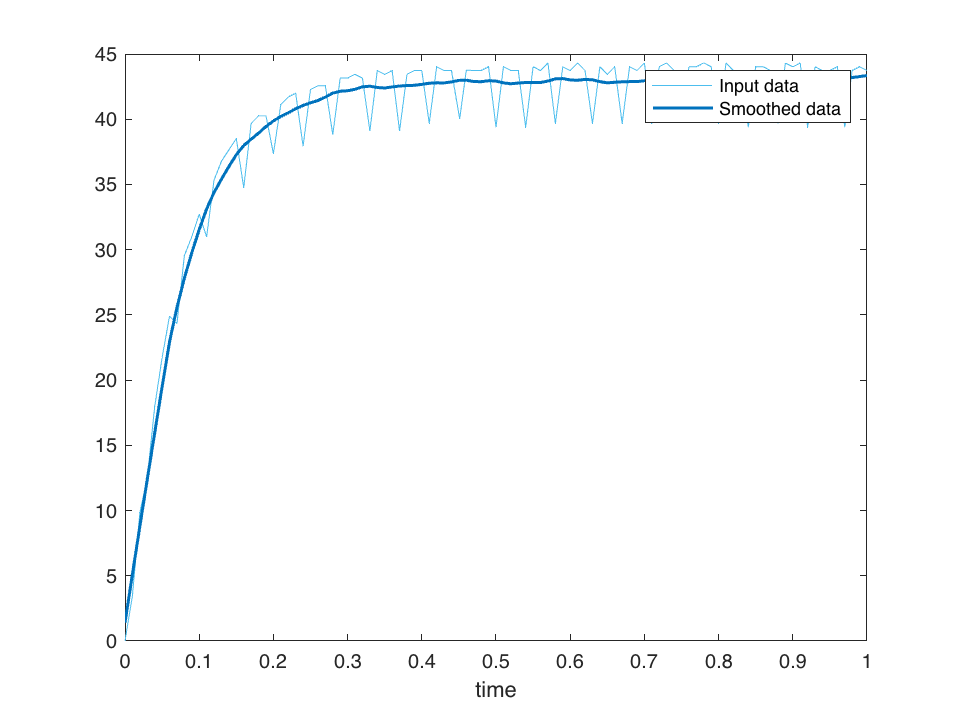

% Smooth input data
smoothedRho = smoothdata(exp1.newRho,"lowess","SmoothingFactor",0.4,...
    "SamplePoints",exp1.time);

% Display results
clf
plot(exp1.time,exp1.newRho,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(exp1.time,smoothedRho,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

new1.newRho = smoothedRho;

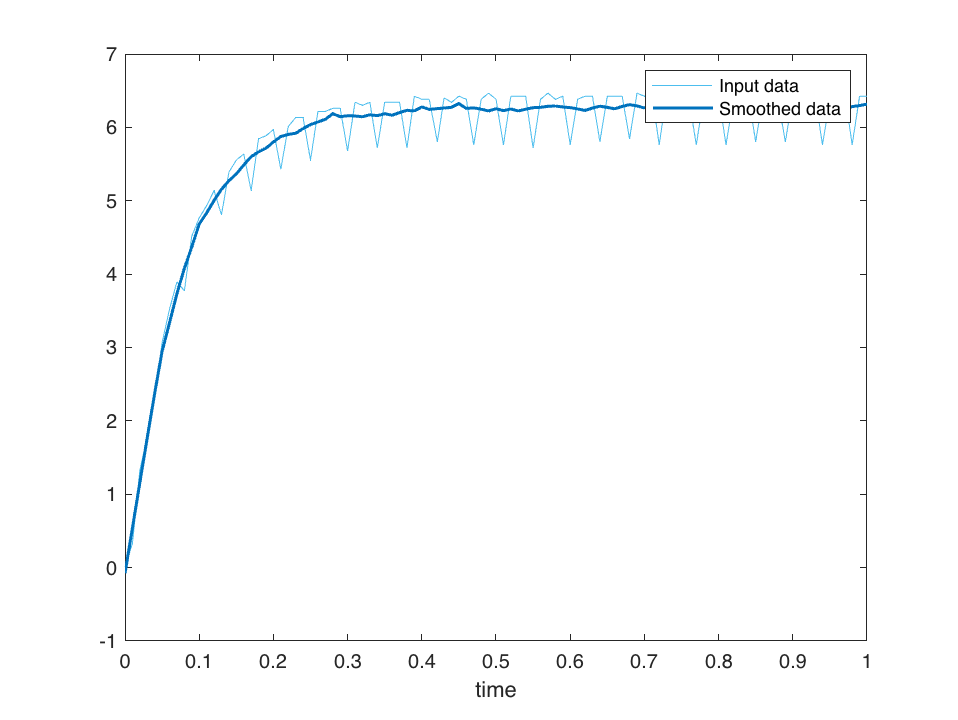

% Smooth input data
smoothedPhi = smoothdata(exp2.newPhi,"lowess","SmoothingFactor",0.25,...
    "SamplePoints",exp2.time);

% Display results
clf
plot(exp2.time,exp2.newPhi,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(exp2.time,smoothedPhi,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

new2.newPhi = smoothedPhi;

Max analogWrite command = 255

max motor.setM1Speed() command = 400

Since the motor command sum is a number out of 800, I need to divide the forward velocity by 800 to get a unit step response.

The maximum motor command difference is 800, corresponding to -400 and 400 on each motor. The rotational velocity needs to be divided by 800

**THIS HAS NOTHING TO DO WITH THE VOLTAGE ON THE BATTERY.**

new1.newRho = new1.newRho/400; new2.newPhi = new2.newPhi/800;

% table2timetable(exp1)
% table2timetable(exp2)

#### Determine Transfer Function of Motor Command to Velocity

Find the steady state velocity of the motor (K)

K_rho = new1.newRho(new1.time > 0.4); K_phi = new2.newPhi(new2.time > 0.4);
K_rho = mean(K_rho), K_phi = mean(K_phi)

K_rho = 0.1074

K_phi = 0.0078

find 0.64 * K and the time constant to find sigma.

K_rho64 = 0.64*K_rho;
K_phi64 = 0.64*K_phi;

% magAt64K_rho = max(new1.newRho(new1.newRho <= 0.64*K_rho+0.1*K_rho & new1.newRho >= 0.64*K_rho-0.1*K_rho))
% magAt64K_phi = max(new2.newPhi(new2.newPhi <= 0.64*K_phi+0.1*K_phi & new2.newPhi >= 0.64*K_phi-0.1*K_phi))
[~,idxRho]=min(abs(new1.newRho-K_rho64))

idxRho = 9

magAt64K_rho=new1.newRho(idxRho)

magAt64K_rho = 0.0695


[~,idxPhi]=min(abs(new2.newPhi-K_phi64))

idxPhi = 9

magAt64K_phi=new2.newPhi(idxPhi)

magAt64K_phi = 0.0051



TC_rho = new1.time(new1.newRho == max(magAt64K_rho));
TC_phi = new2.time(new2.newPhi == max(magAt64K_phi));
sigmaRho = mean(1./TC_rho)

sigmaRho = 12.5000

sigmaPhi = mean(1./TC_phi)

sigmaPhi = 12.5000

With K and sigma, create the velocity and position transfer functions

s = tf('s');
velTF_rho = K_rho*(sigmaRho)/(s+sigmaRho);
velTF_rho.InputName = "Command Sum";
velTF_rho.OutputName = "Forward Velocity"

velTF_rho =
 
  From input "Command Sum" to output "Forward Velocity":
   1.342
  --------
  s + 12.5
 
Continuous-time transfer function.




velTF_phi = K_phi*(sigmaPhi)/(s+sigmaPhi);
velTF_phi.InputName = "Command Difference";
velTF_phi.OutputName = "Rotational Velocity"

velTF_phi =
 
  From input "Command Difference" to output "Rotational Velocity":
  0.09798
  --------
  s + 12.5
 
Continuous-time transfer function.




posTF_rho = velTF_rho*(1/s);
posTF_rho.InputName = "Command Sum";
posTF_rho.OutputName = "Forward Position";

posTF_phi = velTF_phi*(1/s);
posTF_phi.InputName = "Command Difference";
posTF_phi.OutputName = "Rotational Position";

#### Plot the processed data (motor unit step response)

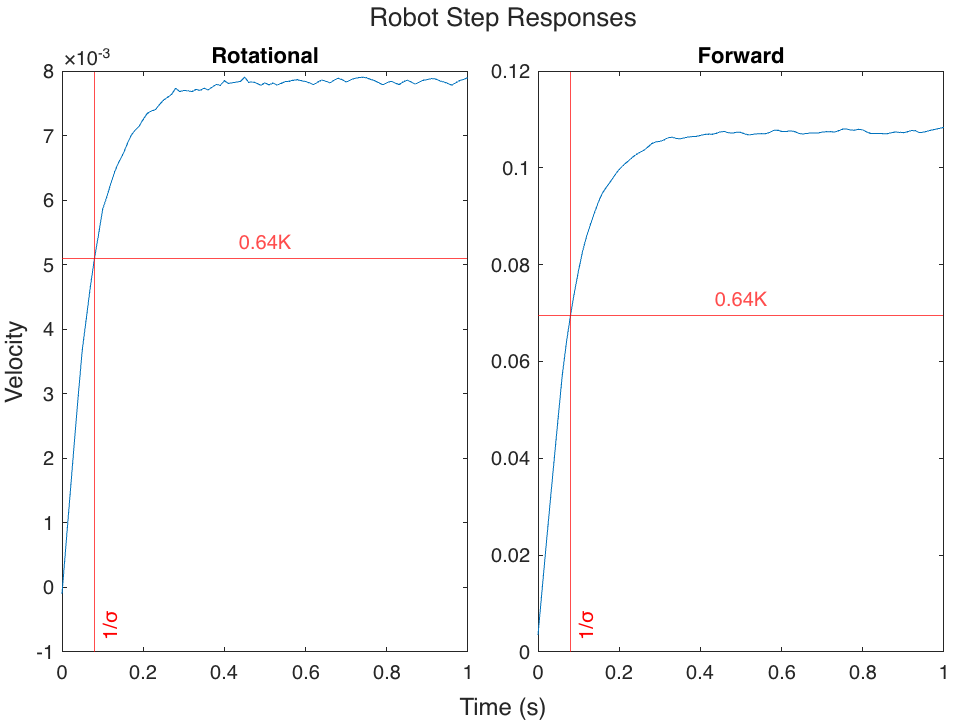

t2 = tiledlayout(1,2,"TileSpacing","compact",'Padding','tight');
xlabel(t2, 'Time (s)')
ylabel(t2, 'Velocity')
title(t2, 'Robot Step Responses')

nexttile
plot(new2.time,new2.newPhi)
title('Rotational')
yline(magAt64K_phi,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_phi,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

nexttile
plot(new1.time,new1.newRho)
title('Forward')
yline(magAt64K_rho,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_rho,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

Turn the generated transfer functions into coefficient arrays for use in Simulink.

posNum_rho = posTF_rho.Numerator;       % Find the numerator coefficients
posNum_rho = posNum_rho{1};             % Convert the numerator to a the right form
posDen_rho = posTF_rho.Denominator;     % Find the denominator coefficients
posDen_rho = posDen_rho{1};             % Convert the denominator to a the right form

velNum_rho = velTF_rho.Numerator;       % Find the numerator coefficients
velNum_rho = velNum_rho{1};             % Convert the numerator to a the right form
velDen_rho = velTF_rho.Denominator;     % Find the denominator coefficients
velDen_rho = velDen_rho{1};             % Convert the denominator to a the right form

posNum_phi = posTF_phi.Numerator;       % Find the numerator coefficients
posNum_phi = posNum_phi{1};             % Convert the numerator to a the right form
posDen_phi = posTF_phi.Denominator;     % Find the denominator coefficients
posDen_phi = posDen_phi{1};             % Convert the denominator to a the right form

velNum_phi = velTF_phi.Numerator;       % Find the numerator coefficients
velNum_phi = velNum_phi{1};             % Convert the numerator to a the right form
velDen_phi = velTF_phi.Denominator;     % Find the denominator coefficients
velDen_phi = velDen_phi{1};             % Convert the denominator to a the right form

#### Compare the Transfer Function with Motor Response

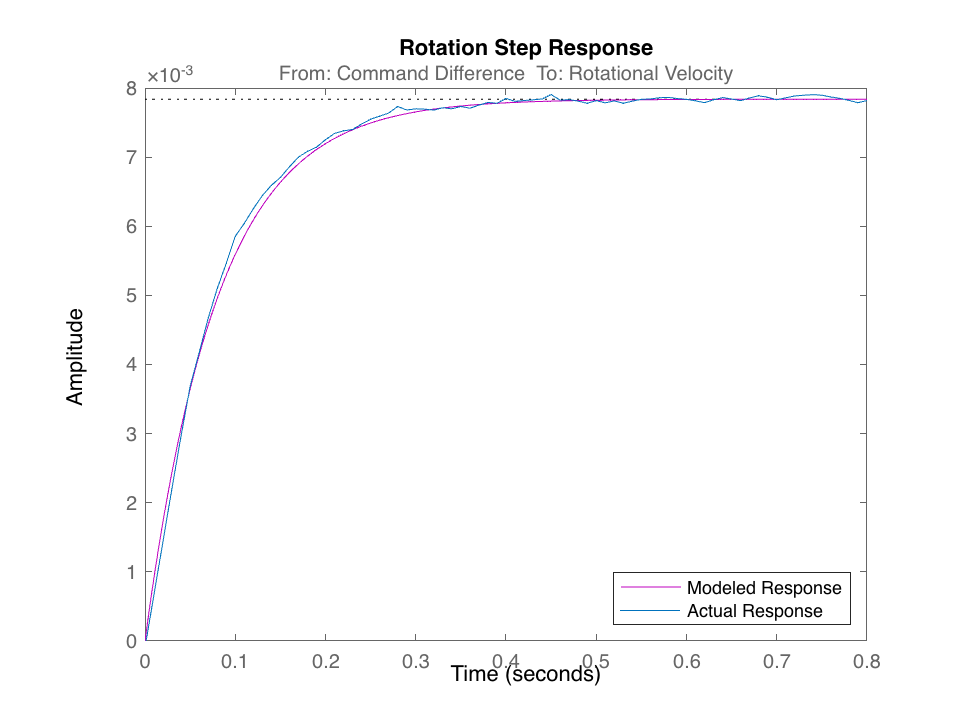

figure
stepplot(velTF_phi,'m')
hold on
plot(new2.time,new2.newPhi)
title("Rotation Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

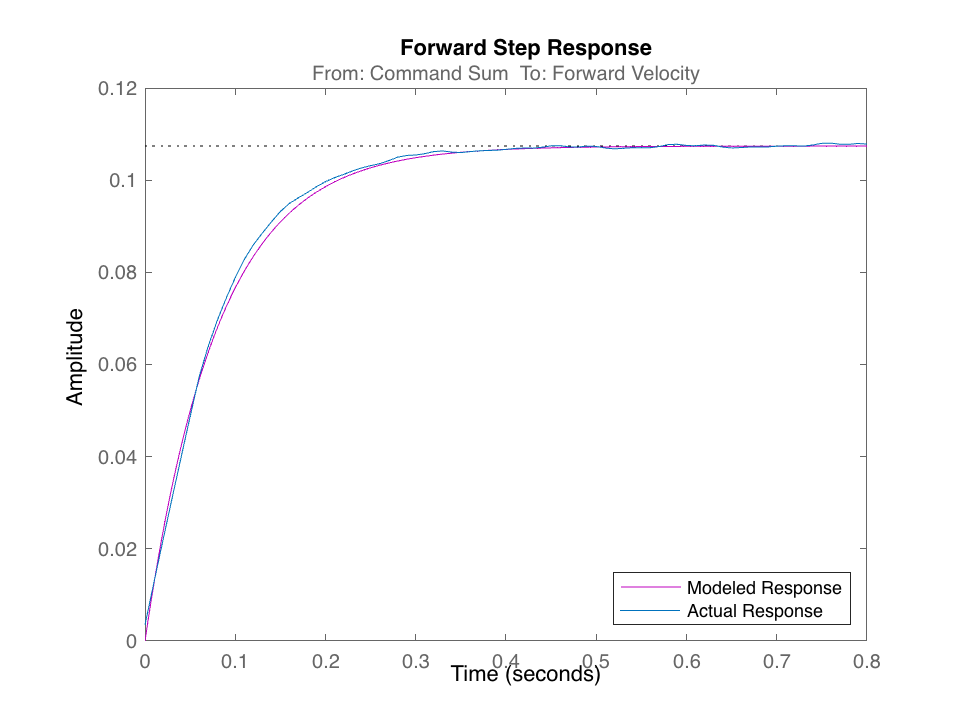


stepplot(velTF_rho,'m')
hold on
plot(new1.time,new1.newRho)
title("Forward Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

Not sure if I want to display both graphs together

% figure
% p1 = subplot(2,1,1);
% stepplot(p1,velTF_phi,'m');
% hold on
% plot(p1,newT.time,exp2.newPhi);
% hold off
% title("Left Motor Step Response")
% 
% p2 = subplot(2,1,2);
% stepplot(p2, velTF_rho,'m');
% hold on
% plot(p2, newT.time,new1.newRho);
% hold off
% title("Right Motor Step Response")
% lgd = legend('Transfer Function','Motor Response','Location','east');

#### Design a PI Controller to Regulate Position

Design a PI controller that achieves closed loop step response specifications of a rise time of 1 second and an overshoot of less than or equal to 12%, with zero steady state error.

figure

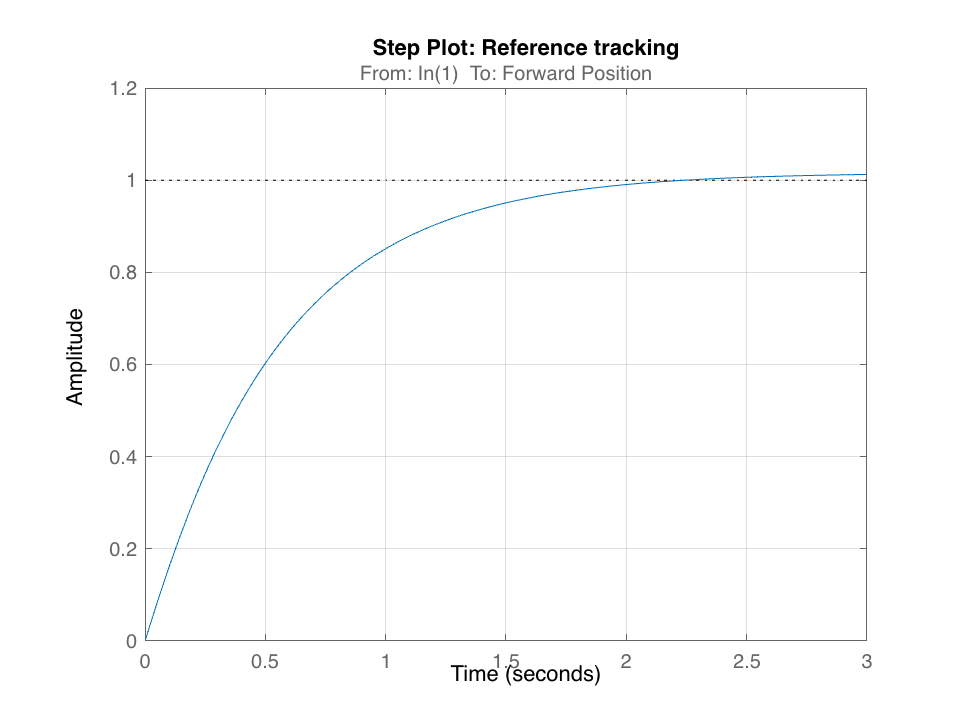

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/1.09276;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.882898;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2,'DesignFocus','reference-tracking');

% PID tuning algorithm for linear plant model
[C_rho,pidInfo] = pidtune(posTF_rho,'PID',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response = getPIDLoopResponse(C_rho,posTF_rho,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 1.1290
    TransientTime: 1.8179
     SettlingTime: 1.8179
      SettlingMin: 0.9041
      SettlingMax: 1.0156
        Overshoot: 1.5647
       Undershoot: 0
             Peak: 1.0156
         PeakTime: 4.4855




% Clear Temporary Variables
clear Response
KP_rho = C_rho.Kp; KI_rho = C_rho.Ki; KD_rho = C_rho.Kd;
fprintf('KP_RHO = %f, KI_RHO = %f, KD_RHO = %f\n',KP_rho, KI_rho,KD_rho)

KP_RHO = 17.108497, KI_RHO = 0.546743, KD_RHO = 1.248057


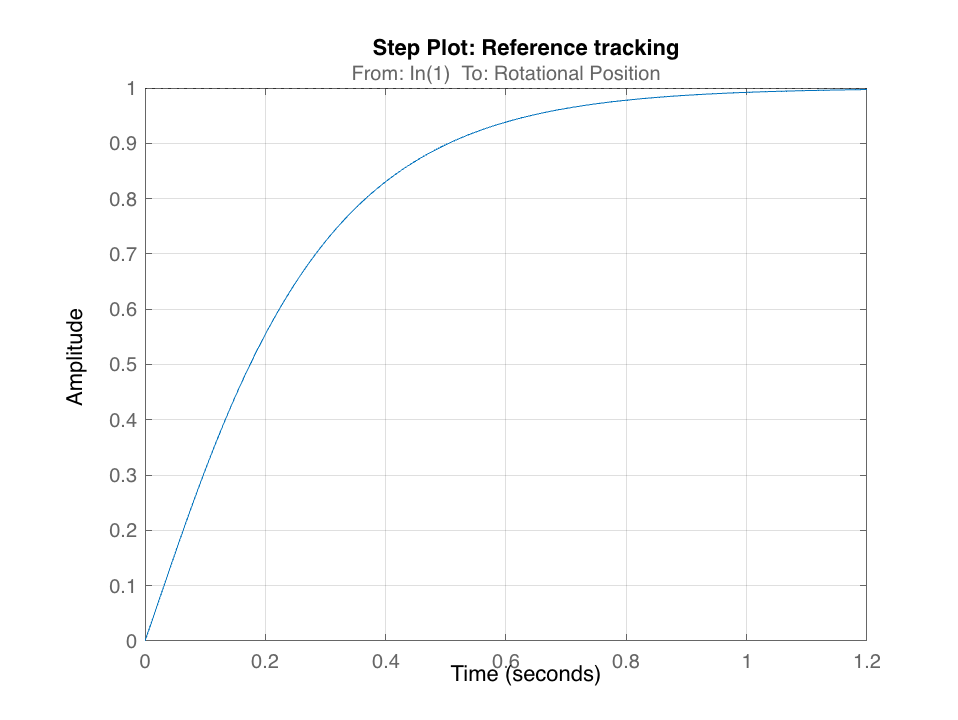

         RiseTime: 0.4733
    TransientTime: 0.8191
     SettlingTime: 0.8191
      SettlingMin: 0.9032
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 1.4012



% Convert Response Time to Bandwidth

% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.474235;

% Define options for pidtune command
opts = pidtuneOptions('DesignFocus','reference-tracking');

% PID tuning algorithm for linear plant model
[C_phi,pidInfo2] = pidtune(posTF_phi,'P',wc,opts);

% Clear Temporary Variables
clear wc opts

% Get desired loop response
Response2 = getPIDLoopResponse(C_phi,posTF_phi,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on

% Display system response characteristics
disp(stepinfo(Response2))

% Clear Temporary Variables
clear Response2
KP_phi = C_phi.Kp; KI_phi = C_phi.Ki; KD_phi = C_phi.Kd;
fprintf('KP_PHI = %f, KI_PHI = %f, KD_PHI = %f\n',KP_phi, KI_phi,KD_phi)

KP_PHI = 551.698830, KI_PHI = 0.000000, KD_PHI = 31.877635


## Designing a controller for forward and rotational speed


$$\overline{V}_{a} = V_{a,1} + V_{a,2}$$



$$\Delta{V}_{a} = V_{a,1} - V_{a,2}$$


Va,1 and Va,2 are the voltage commands for the left and right motors

$\overline{V}_a$ is the magnitude of the combined voltage commands. Used for the forward speed $\dot{\rho}_d$ 

$\Delta V_a$ is the difference between the two voltage commands. Used for rotational speed $\dot{\phi}_d$

Forward velocity to voltage command:            $G_{\rho}(s) = \frac{\dot{\rho}(s)}{\overline{V}_a(s)}$

Rotational velocity to voltage command:        $G_{\phi}(s) = \frac{\dot{\phi}(s)}{\Delta V_a(s)}$